%***************************************
%Author: Jinbing Ying
%Date: 2020-5-10
%***************************************

## 流程初始化

clear all; close all;
x_I=1; y_I=1;           % set start point
x_G=700; y_G=700;       % set goal point
Thr=50;                 %set goal threshold
Delta= 30;              % set step size


## Initialize the process

T.v(1).x = x_I;         % T is the tree and v is the node adding start point to the tree
T.v(1).y = y_I; 
T.v(1).xPrev = x_I;     % Start node has parent node as itself
T.v(1).yPrev = y_I;
T.v(1).dist=0;          %distance between current node and parent node
T.v(1).indPrev = 0;     %

## Build the node tree

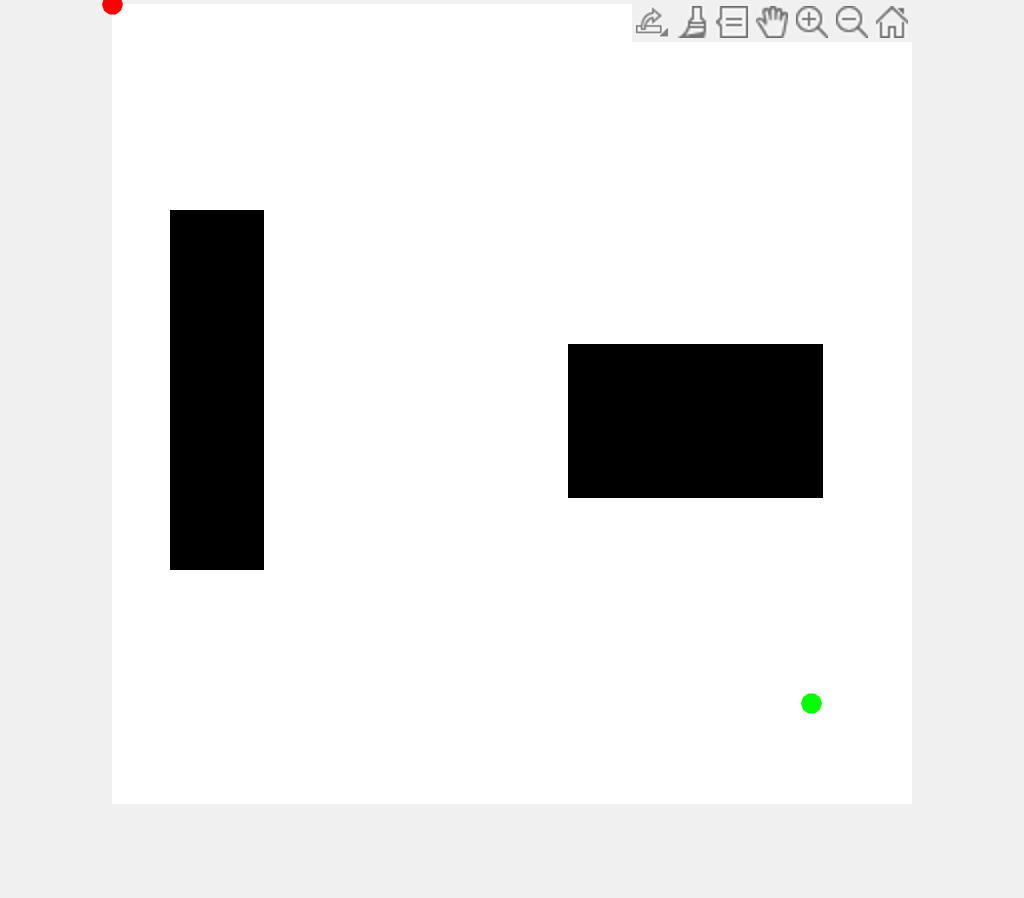

set(gcf,'Visible','on');
figure(1);
ImpRgb=imread('newmap01.png');
Imp=rgb2gray(ImpRgb);
imshow(Imp)
xL=size(Imp,1);
yL=size(Imp,2);
hold on
plot(x_I, y_I, 'ro', 'MarkerSize',10, 'MarkerFaceColor','r');
plot(x_G, y_G, 'go', 'MarkerSize',10, 'MarkerFaceColor','g');

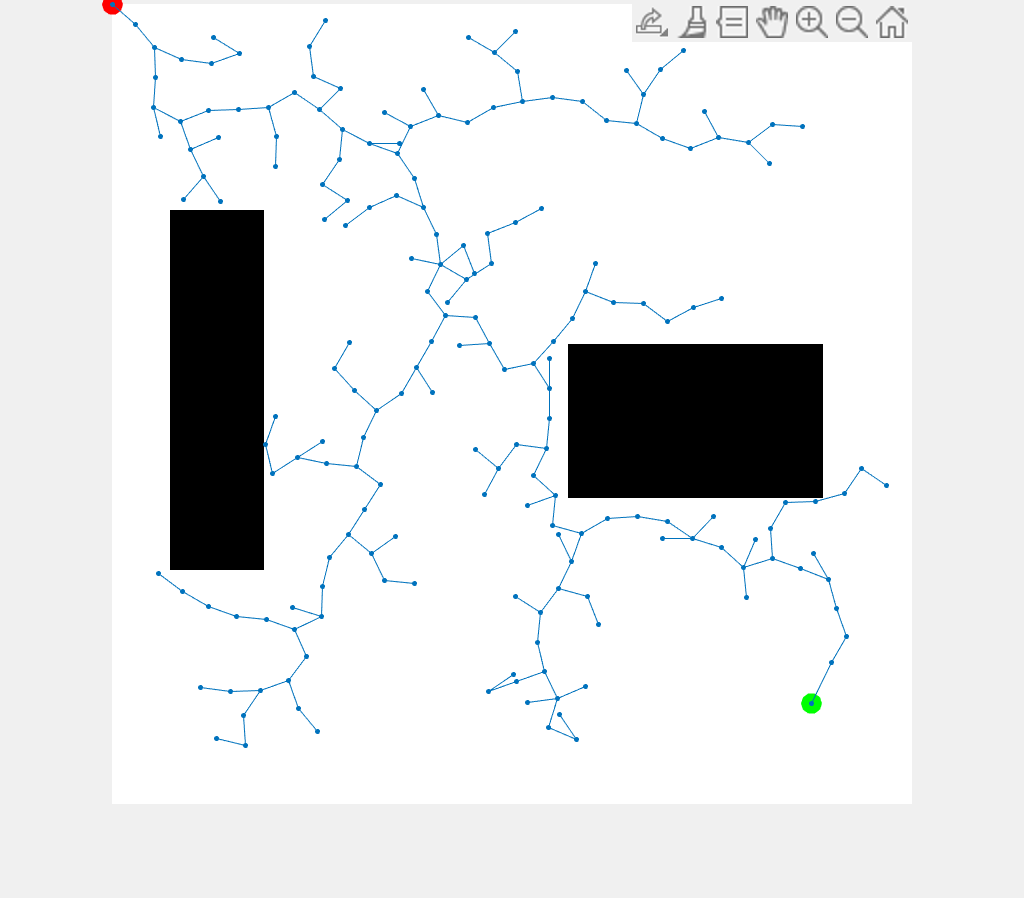


count=1;
for iter = 1:3000
    x_rand=[];
    %Get a random point on the map as x_rand
    %（x_rand(1),x_rand(2)
    x_rand(1) = ceil(rand()*800);
    x_rand(2) = ceil(rand()*800);
    
   
    x_near=[];
    %traverse the tree and find the nearest node to the current node    
    min_dist = 1000;
    for i= 1 : count
        dist = sqrt( ( T.v(i).x - x_rand(1) )^2 + ( T.v(i).y - x_rand(2) )^2 );
        if dist < min_dist
            min_dist = dist;
            index = i;
        end
    end
    
    x_near(1) = T.v(index).x;
    x_near(2) = T.v(index).y;
    
    x_new=[];
    %get x_new node with the step size and the dist between x_rand and
    %x_near which is min_dist
    x_new(1) = x_near(1) + round((x_rand(1) - x_near(1))* Delta/min_dist);
    x_new(2) = x_near(2) + round((x_rand(2) - x_near(2))* Delta/min_dist);
    %chec if collision free
    if ~collisionChecking(x_near,x_new,Imp) 
        continue;
    end
    count=count+1;
    
    %insert xnew to the tree and the parent node is x_near
    T.v(count).x = x_new(1);
    T.v(count).y = x_new(2);
    T.v(count).xPrev = x_near(1);
    T.v(count).yPrev = x_near(2);
    T.v(count).dist = min_dist;
    T.v(count).indPrev = index;
    %check if reach termination condition which is the threshold to the
    %goal point 
    new_dist = sqrt((x_new(1) - x_G)^2 + (x_new(2) - y_G)^2);
    if new_dist <= Thr
        plot(x_new(1), x_new(2), 'bo', 'MarkerSize', 2, 'MarkerFaceColor','b');
        line([x_new(1) x_near(1)], [x_new(2) x_near(2)], 'Marker', '.', 'LineStyle','-');
        line([x_G x_new(1)], [y_G x_new(2)], 'Marker', '.', 'LineStyle', '-');
        break;
    end
    
    
   %draw the path between x_new and x_near use hold on to draw on the same
   %figure
    plot(x_new(1), x_new(2), 'bo', 'MarkerSize',2, 'MarkerFaceColor','b'); % 绘制x_new
    line( [x_new(1) x_near(1)], [x_new(2) x_near(2)], 'Marker','.','LineStyle','-'); %连接x_near和x_new
    hold on;
   
    
   
   pause(0.1); %pause for 0.1sec to show the animation
end

## Path found and reverse search every node on the path

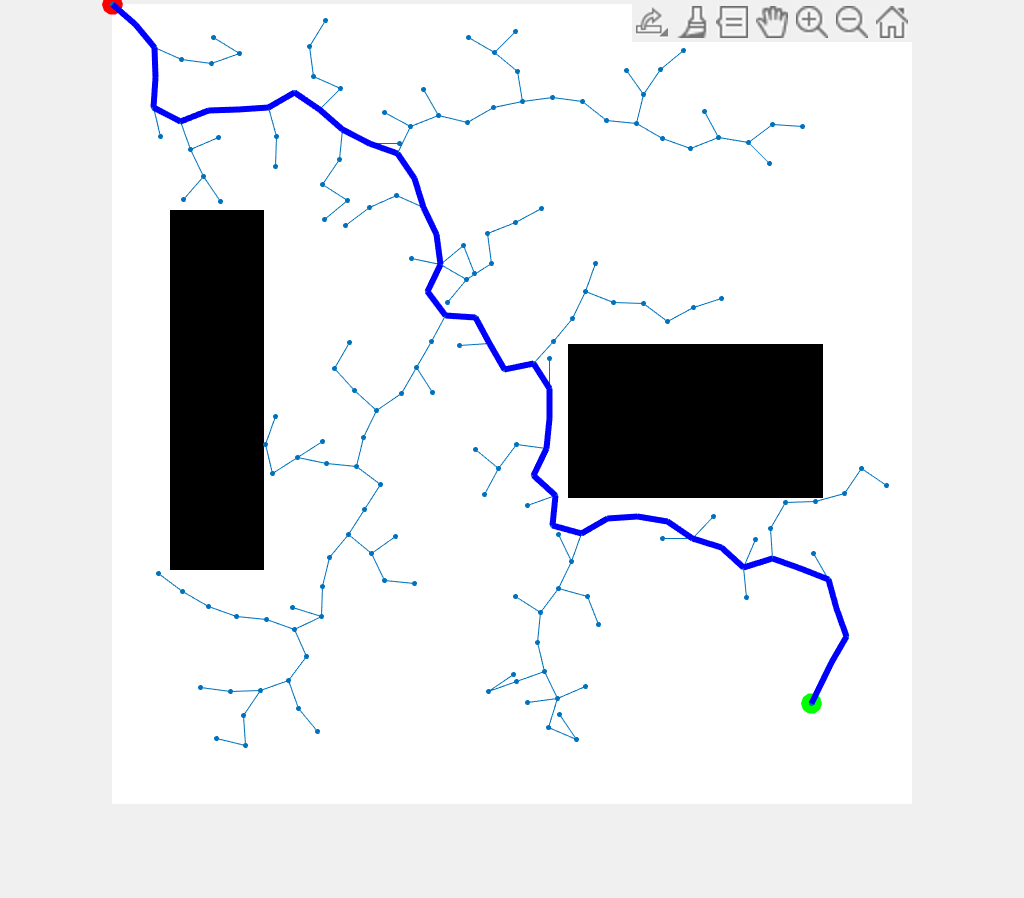

if iter < 2000
    path.pos(1).x = x_G; path.pos(1).y = y_G;
    path.pos(2).x = T.v(end).x; path.pos(2).y = T.v(end).y;
    pathIndex = T.v(end).indPrev; 
    j=0;
    while 1
        path.pos(j+3).x = T.v(pathIndex).x;
        path.pos(j+3).y = T.v(pathIndex).y;
        pathIndex = T.v(pathIndex).indPrev;
        if pathIndex == 1
            break
        end
        j=j+1;
    end  
    path.pos(end+1).x = x_I; path.pos(end).y = y_I; 
    for j = 2:length(path.pos)
        plot([path.pos(j).x; path.pos(j-1).x;], [path.pos(j).y; path.pos(j-1).y], 'b', 'Linewidth', 3);
    end
else
    disp('Error, no path found!');
end